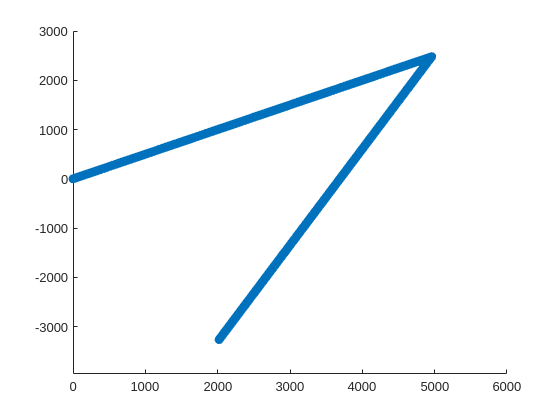

waypoints = [0 0 0; 5000 2500 15; 2000 -3300 0];

max_hor_vel = 25;
max_vert_vel = 3;
max_hor_accel = 2.5;
max_vert_accel = 1;

refresh_rate = 2;
time_delta = 1 / refresh_rate;

cnt = 1;

posx = zeros(1,10000);
posy = zeros(1,10000);
posz = zeros(1,10000);
velx = zeros(1,10000);
vely = zeros(1,10000);
velz = zeros(1,10000);

for i=1:length(waypoints)
    
    if i == 1
        x1 = waypoints(1, 1);
        y1 = waypoints(1, 2);
        z1 = waypoints(1, 3);
        state = 'initial';

        vx = 0;
        vy = 0;
        vz = 0;

        continue;
    end
    
    x2 = waypoints(i, 1);
    y2 = waypoints(i, 2);
    z2 = waypoints(i, 3);

    while(abs(x2-x1) > 25 && abs(y2-y1) > 25)
        cnt = cnt + 1;
    
        heading = atan2(x2 - x1, y2 - y1);
        if heading < 0
            heading = heading + 2 * pi;
        end
        
        current_velocity = sqrt( vx^2 + vy^2 + vz^2 );
        current_velocity = current_velocity + max_hor_accel * time_delta;
        if current_velocity > max_hor_vel
            current_velocity = max_hor_vel;
        end
    
        vx = current_velocity * sin(heading);
        vy = current_velocity * cos(heading);
    
        x1 = x1 + vx * time_delta;
        y1 = y1 + vy * time_delta;
    
        posx(cnt) = x1;
        posy(cnt) = y1;
        posz(cnt) = z1;
        velx(cnt) = vx;
        vely(cnt) = vy;
        velz(cnt) = vz;
    end
end

posx = posx(1:cnt);
posy = posy(1:cnt);
posz = posz(1:cnt);
velx = velx(1:cnt);
vely = vely(1:cnt);
velz = velz(1:cnt);

scatter(posx, posy);
xlim([min(waypoints(:,1)) max(waypoints(:,1))] .* 1.2);
ylim([min(waypoints(:,2)) max(waypoints(:,2))] .* 1.2);

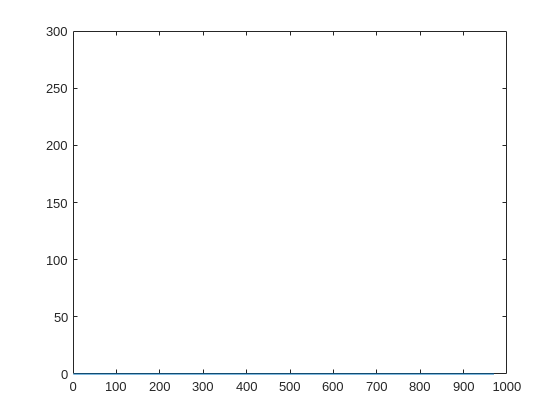


plot(posz);
ylim([0 200*1.5]);

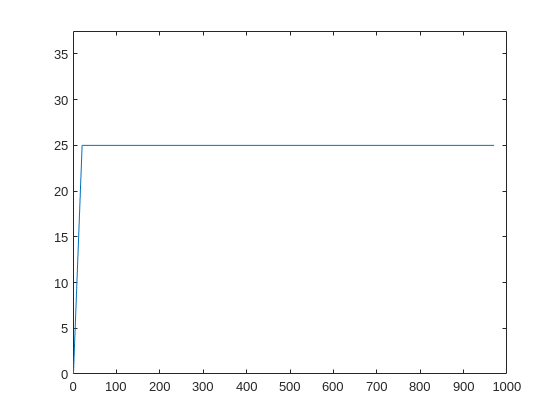


plot(sqrt(velx.^2 + vely.^2));
ylim([0 max_hor_vel * 1.5]);

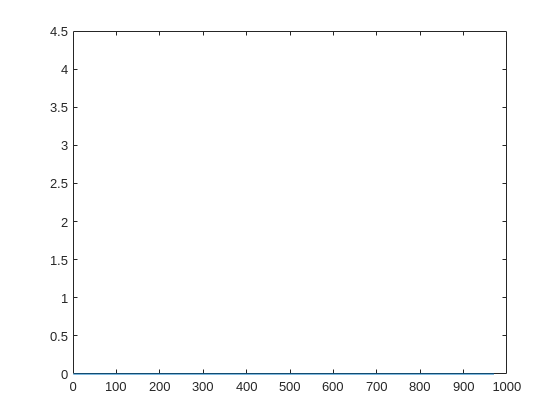


plot(velz);
ylim([0 max_vert_vel * 1.5]);